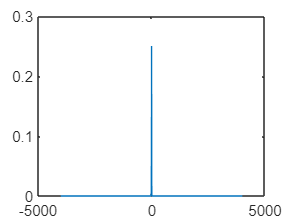

% PDF CDF of Laplace Distribution for mu=2 and b = 2 
% and its variance
NUMBER_OF_STEPS = 100; %Per unit length
RANGE = 80;
ARRAY_SIZE = NUMBER_OF_STEPS*RANGE ;
x = zeros(1,ARRAY_SIZE);
y = zeros(1,ARRAY_SIZE);
z = zeros(1,ARRAY_SIZE);
var = 0;
mu = 2;
b = 2;
for i = 1:ARRAY_SIZE
    v = mu - RANGE/2 + i/NUMBER_OF_STEPS;
    x(i) = v; 
    t =  -(abs(v - mu))/ b ;
    y(i) = exp(t) / (2*b);
    z(i+1) = z(i) + y(i)/NUMBER_OF_STEPS;  
    var = var + (y(i)*(v-mu)^2)/NUMBER_OF_STEPS;
end

plot(x,y);

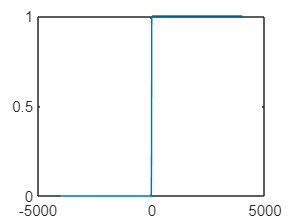


m = z(1,1:ARRAY_SIZE);
plot(x,m);


var

var = 8.0000